## Quantum Fourier Transform

We want to implement an algorithm to generate an N-bit Quantum Fourier Transform (QFT) circuit. We define a function that does so:

function qc = myQFT(n_qubits)
    gates = [];
    for i=1:n_qubits
        gate_1 = hGate(i);
        gates = [gates;gate_1];
        for j=i:n_qubits
            if (i ~= j)
                gate_1 = cr1Gate(j, i, pi./2.^j);
                gates = [gates;gate_1];
            end
    
        end
    end
    for i=1:floor(n_qubits/2)
        gate_1 = swapGate(i, n_qubits + 1 - i);
        gates = [gates;gate_1];
    end
    qc = quantumCircuit(gates,n_qubits);
end

Let's now use it to generate a QFT applied to 6 qubitsù:

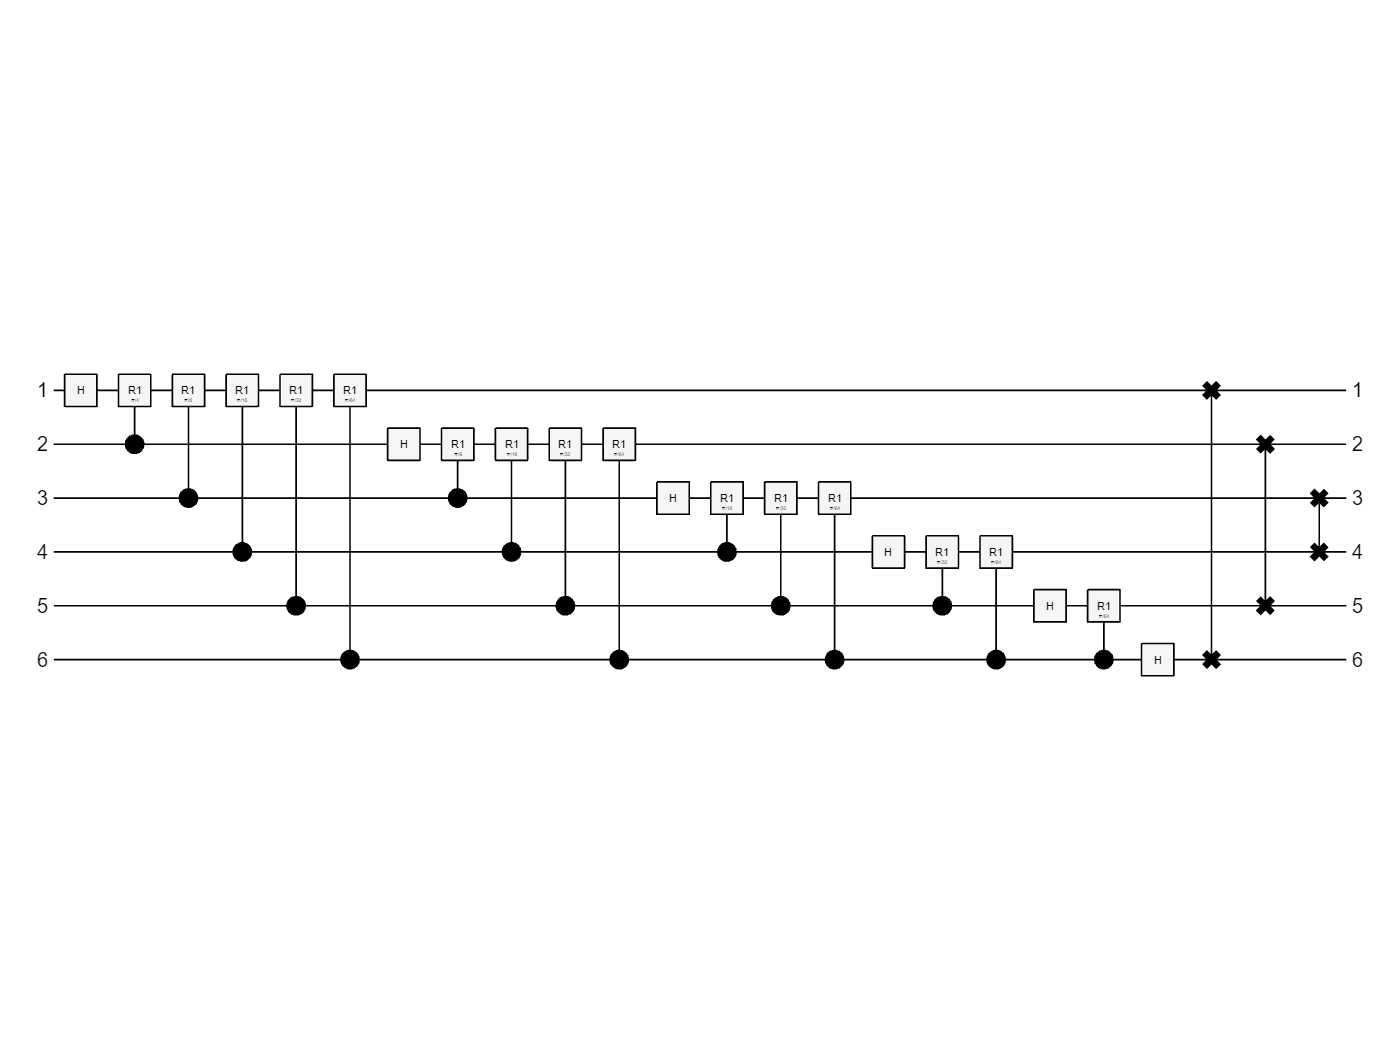

qc = myQFT(6);
plot(qc)

The same implementation can be acheived using the *qftGate *directly, which is part of the MATLAB library.

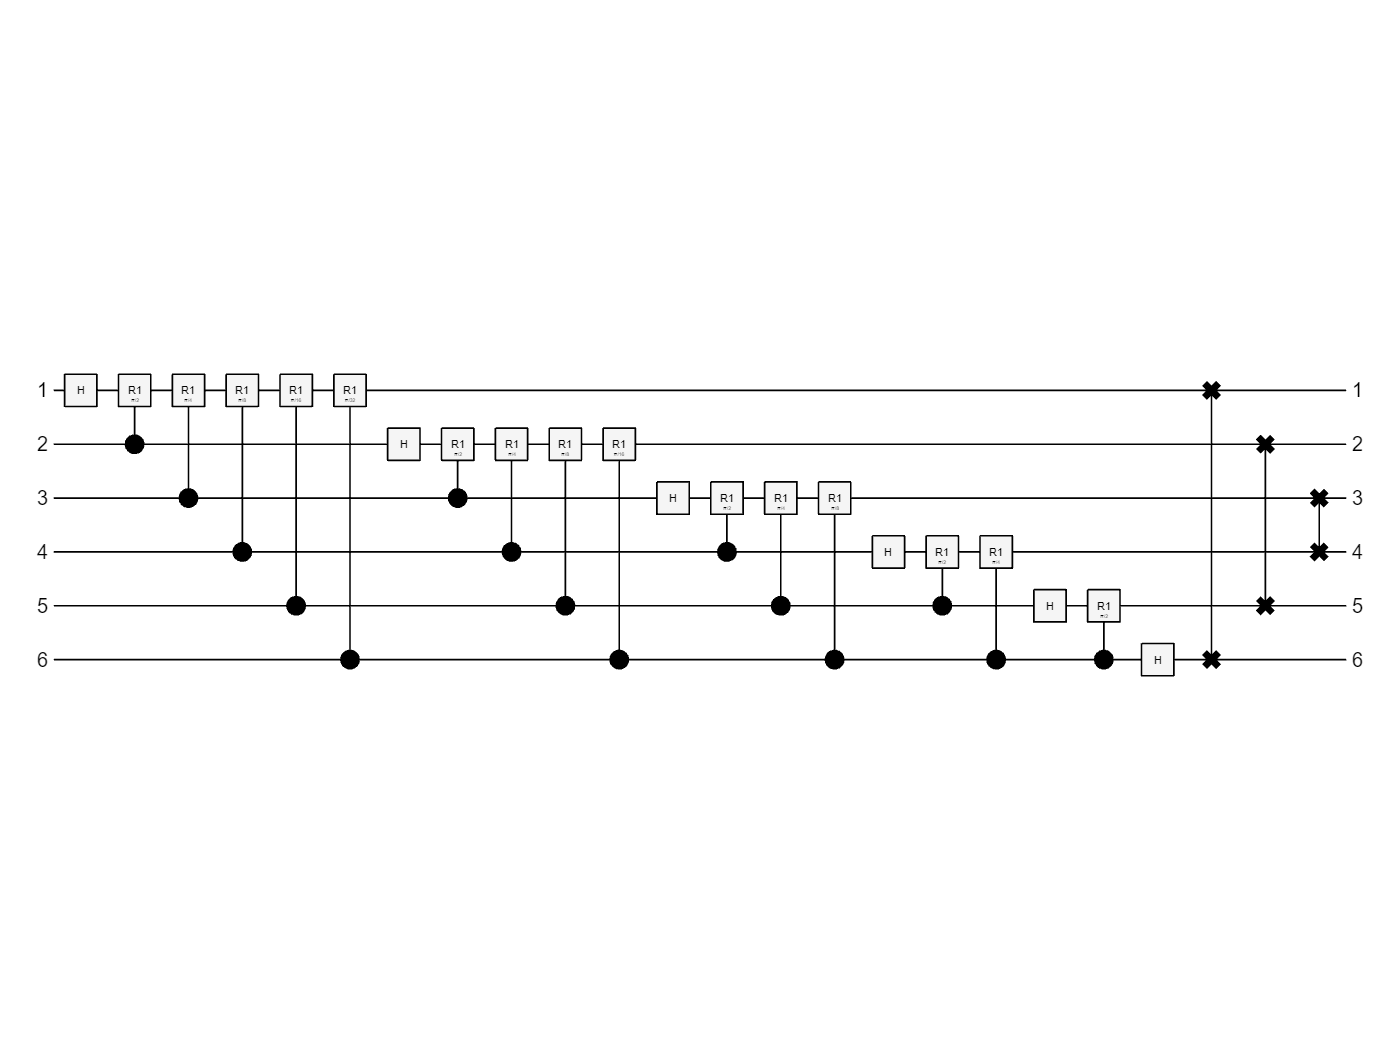

cg = qftGate(1:6);
plot(cg)

Let's simulate it:

S = simulate(qc)

S =   QuantumState with properties:

    BasisStates: [64×1 string]
     Amplitudes: [64×1 double]
      NumQubits: 6


We can also show such a state as a mathematical expression using Dirac bra-ket notation:

f = formula(S, basis = "Z") % the expression uses the computational basis {|0>, |1>}

f =     "0.125 * |000000> +
     0.125 * |000001> +
     0.125 * |000010> +
     0.125 * |000011> +
     0.125 * |000100> +
     0.125 * |000101> +
     0.125 * |000110> +
     0.125 * |000111> +
     0.125 * |001000> +
     0.125 * |001001> +
     0.125 * |001010> +
     0.125 * |001011> +
     0.125 * |001100> +
     0.125 * |001101> +
     0.125 * |001110> +
     0.125 * |001111> +
     0.125 * |010000> +
     0.125 * |010001> +
     0.125 * |010010> +
     0.125 * |010011> +
     0.125 * |010100> +
     0.125 * |010101> +
     0.125 * |010110> +
     0.125 * |010111> +
     0.125 * |011000> +
     0.125 * |011001> +
     0.125 * |011010> +
     0.125 * |011011> +
     0.125 * |011100> +
     0.125 * |011101> +
     0.125 * |011110> +
     0.125 * |011111> +
     0.125 * |100000> +
     0.125 * |100001> +
     0.125 * |100010> +
     0.125 * |100011> +
     0.125 * |100100> +
     0.125 * |100101> +
     0.125 * |100110> +
     0.125 * |100111> +
     0.125 * |101000> +
     0.125 *

and we can even transform such a formula into another reference basis:

f2 = formula(S, basis="X") % we are now using the Hadamard basis {|+>, |->}

f2 = "1 * |++++++>"

Let's see the final basis states and amplitudes:

T = table(S.BasisStates, S.Amplitudes, ...
    VariableNames=["Basis States","Amplitudes"])

T = 64×2 table
    Basis States    Amplitudes
    ____________    __________

      "000000"        0.125   
      "000001"        0.125   
      "000010"        0.125   
      "000011"        0.125   
      "000100"        0.125   
      "000101"        0.125   
      "000110"        0.125   
      "000111"        0.125   
      "001000"        0.125   
      "001001"        0.125   
      "001010"        0.125   
      "001011"        0.125   
      "001100"        0.125   
      "001101"        0.125   
      "001110"        0.125   
      "001111"        0.125   


Let's also plot the corresponding histogram:

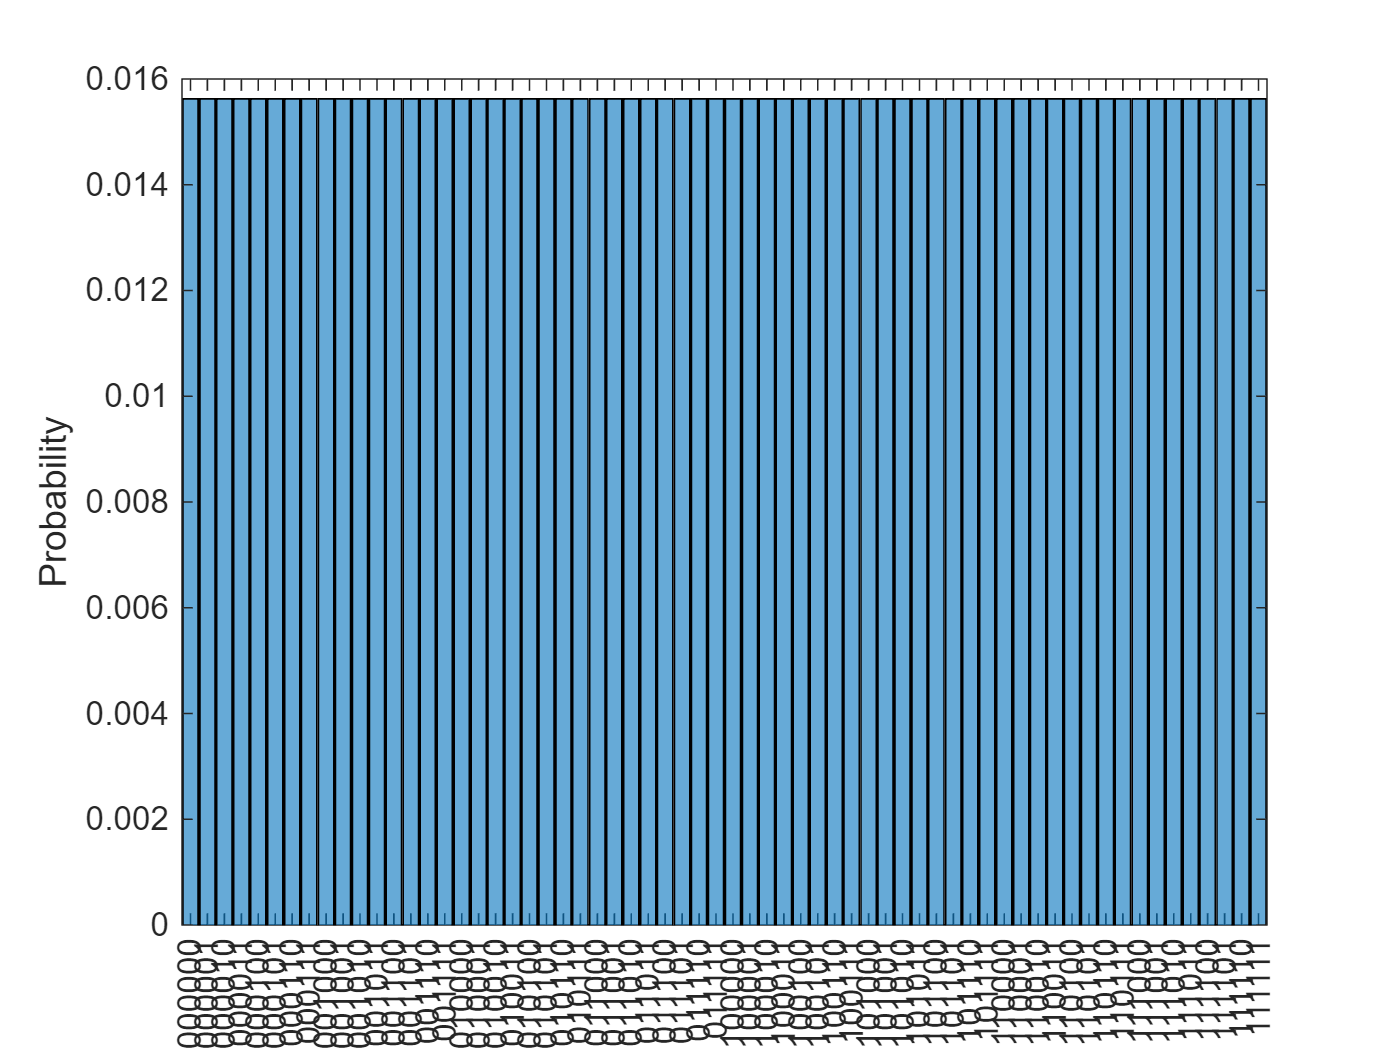

histogram(S)

M = randsample(S, 1000)

M =   QuantumMeasurement with properties:

    MeasuredStates: [64×1 string]
            Counts: [64×1 double]
     Probabilities: [64×1 double]
         NumQubits: 6


T = table(M.Counts,M.Probabilities,M.MeasuredStates, ...
    VariableNames=["Counts","Probabilities","States"])

T = 64×3 table
    Counts    Probabilities     States 
    ______    _____________    ________

      25          0.025        "000000"
      20           0.02        "000001"
      17          0.017        "000010"
      14          0.014        "000011"
      13          0.013        "000100"
      20           0.02        "000101"
      11          0.011        "000110"
      17          0.017        "000111"
      15          0.015        "001000"
      13          0.013        "001001"
      16          0.016        "001010"
      16          0.016        "001011"
      21          0.021        "001100"
      13          0.013        "001101"
      19          0.019        "001110"
      15          0.015        "001111"
